# 课题 1 ： 可激发系统的模拟： Hodgkin-Huxley 神经元模型

## 可激发系统

 可激发介质/系统 (excitable medium/system): 简言之就是具有 “可激励性”的介质, 也叫激励介质  

“可激励性”所对应的英文单词是“excitability”. 这个词在不同 的学科里有不同的译法: 物理学中叫可激发性, 医学中叫兴奋性、 敏感性, 生理学中叫刺激反应性 这里所指的“可激励性”是当介质 受到小扰动时, 介质很快恢复到平衡态 (静态); 但当扰动超过某一 阈值时, 介质将有一个快速又陡峭的响应, 呈现激发状态  

## 神经元

大脑中神经元数目巨大 ~10^11  

神经元形状及其多样  

图中的标注及其翻译：

Soma ：胞体


$$\textrm{Neurites}\textrm{：神经突}\left\lbrace \begin{array}{ll}
\textrm{Dendrites}\textrm{树突} & \\
\textrm{Axon}\textrm{：轴突} & 
\end{array}\right.$$


## 神经元的可激发性

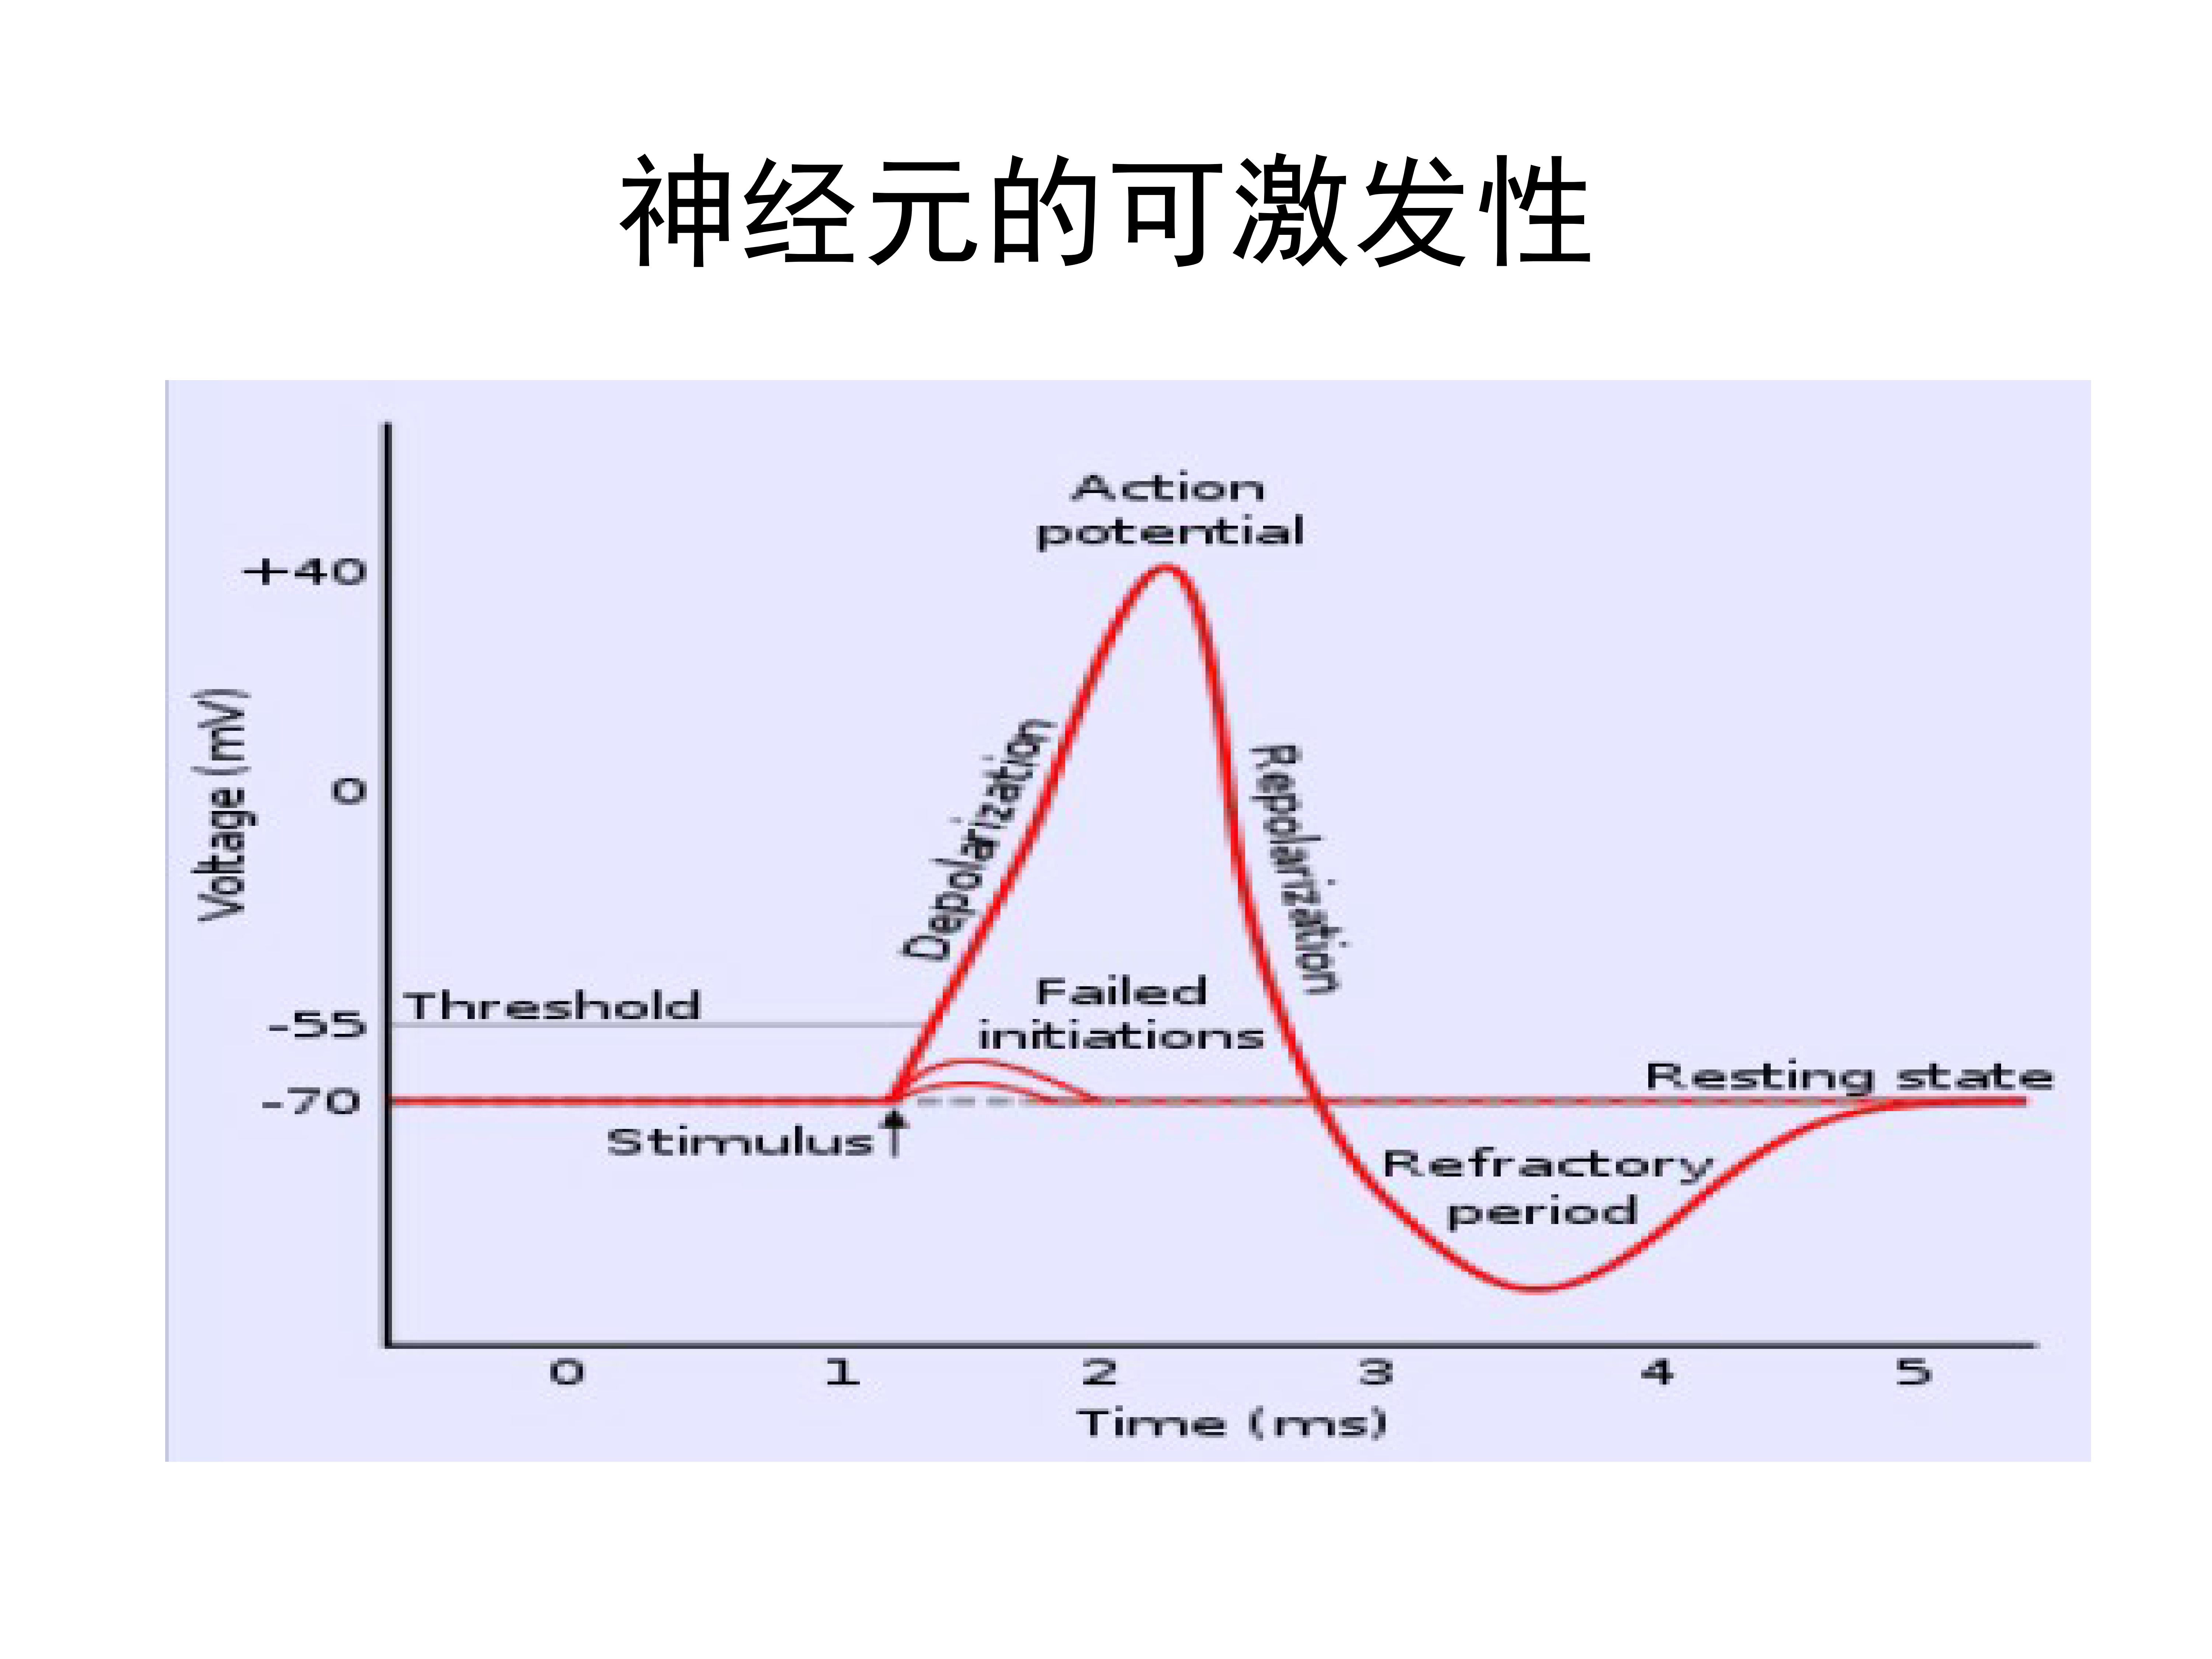

图中的标注及其翻译：

  Action potential ：动作电势

  Depolarization ：去极化

  Repolarization ：复极化

  Failed initiations ：失败的启动

  Threshold ：阈值

  Resting state ：静息态

  Stimulus ：刺激

  Refractory period 不应期

神经元在受到刺激时膜电位随时间变化的过程，称为**动作电势  **

**Y轴 :** 电压，单位：mV 神经元细胞膜内外的电位差  

**X轴:**时间，单位：毫秒

- **三个电位水平 Potential Levels:**

- **Resting state (静息态):** 约 -70 mV 神经元在未受刺激时的稳定电位

- **Threshold (阈值):** 约 -55 mV 临界电位

- **峰值:** 约 +40 mV 动作电势达到的最高电位

- **事件：**

- **Stimulus (刺激):** 在 1 ms 稍过一点的位置，一个外部刺激被施加  

- **Failed initiations (失败的启动):** 图中阈值下方的小波形  这表示刺激强度太弱，没有使膜电位达到 -55 mV 的阈值，因此无法触发一个完整的动作电势，电位很快就回落到静息态  

- **Depolarization (去极化):** 当一个足够强的刺激使膜电位达到阈值 (-55 mV) 后，膜电位开始急剧上升，从负值变为正值，一直达到 +40 mV 的峰值  

- **Action potential (动作电势):** 整个快速的电位“尖峰”（从去极化开始到复极化结束）被称为动作电势  图中的标签也特指其峰值  

- **Repolarization (复极化):** 达到峰值后，膜电位迅速下降，从 +40 mV 降回负值  

- **Refractory period (不应期):** 膜电位在复极化后，会短暂地降到比静息态（-70 mV）更低的水平  在这个时期，神经元对新的刺激反应能力降低（或完全不反应）  之后，电位会逐渐恢复到 -70 mV 的静息态  

## 动作电势的特性

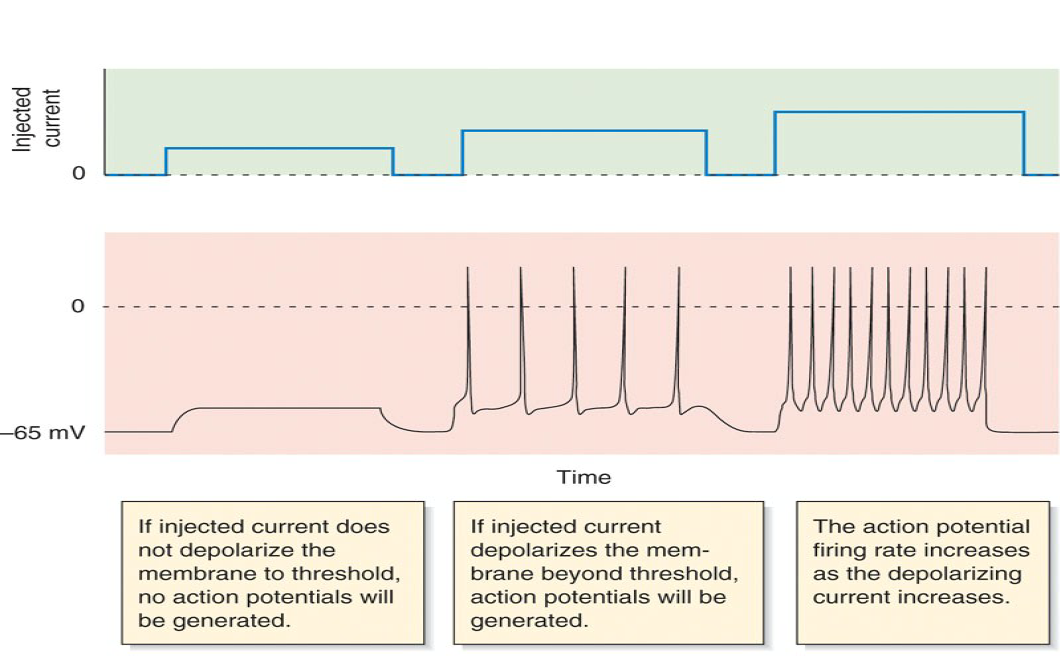

  Injected current ：注入电流

1.  If injected current does not depolarize the membrane to threshold, no action potentials will be generated.

    如果注入的电流没有使细胞膜去极化到阈值，则不会产生动作电势  

2.  If injected current depolarizes the membrane beyond threshold, action potentials will be generated.

    如果注入的电流使细胞膜去极化超过阈值，则会产生动作电势  

3.  The action potential firing rate increases as the depolarizing current increases.

    随着去极化电流的增加，动作电势的发放频率增加 

## 神经元的数学建模

### 细胞膜与离子通道

  channel 通道

  pore 孔隙

  lipid bilayer 脂双层

### 等效电路

等效成了三个电阻和一个电容并联，并且在每个电阻的回路串上电池，每个电迟代表了对应离子的能斯特电位，电阻则代表了离子泵的耗能

这个模型中的能量来源是电池提供的，即营养物质的摄入

#### PPT上指出的公式

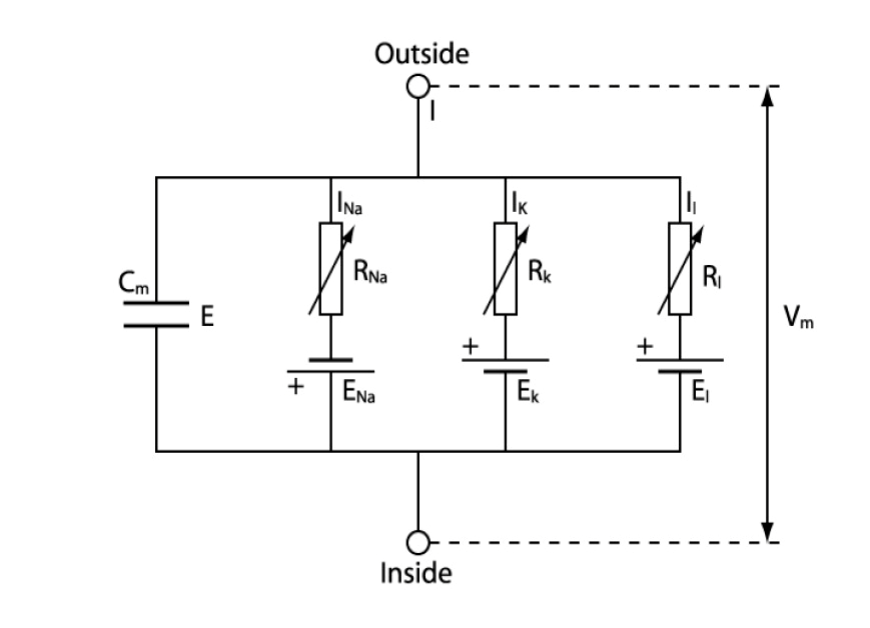


$$C_m \frac{dV_m }{dt}+I_{ion} =I_{ext}$$



$$I_{ion} =\sum_k I_k =\sum_k G_k (V_m -E_k )\ldotp$$


这里的$I_{ext}$ 是外部总电流，$I_{ion}$指离子电流之和

离子有三种，Na， K，还有泄露（主要是氯离子）

 $V_m$ 是指内外模的电势差，$G_k$指电导

#### PPT中给出的微分方程是


$$$$
\begin{cases}
C_m \frac{dV}{dt} = -g_L(V-E_L) - \bar{g}_{Na} m^3 h (V-E_{Na}) - \bar{g}_K n^4 (V-E_K) + I_{app} \\
\frac{dm}{dt} = \alpha_m(V)(1-m) - \beta_m(V)m \\
\frac{dh}{dt} = \alpha_h(V)(1-h) - \beta_h(V)h \\
\frac{dn}{dt} = \alpha_n(V)(1-n) - \beta_n(V)n
\end{cases}
$$$$


HH 模型描述了动作电势的发生过程  

#### PPT中给出的参数是

电容：$C = 1 \mu\text{F/cm}^2$

各离子的能斯特电位和对应的电导：


$$\begin{array}{lrr}
\hline\hline
x & E_x \text{ [mV]} & g_x \text{ [mS / cm}^2\text{]} \\
\hline
\text{Na} & 55 & 40 \\
\text{K} & -77 & 35 \\
\text{L} & -65 & 0.3 \\
\hline\hline
\end{array}$$


对应的 alpha和beta函数：


$$





\begin{array}{lcc}
\hline\hline
x & \alpha_x (u / \text{ mV}) \text{ [ms}^{-1}\text{]} & \beta_x (u / \cdot \text{ mV}) \text{ [ms}^{-1}\text{]} \\
\hline
n & 0.02(u-25) / [1-e^{-(u-25)/9}] & -0.002(u-25) / [1-e^{(u-25)/9}] \\
m & 0.182(u+35) / [1-e^{-(u+35)/9}] & -0.124(u+35) / [1-e^{(u+35)/9}] \\
h & 0.25 e^{-(u+90)/12} & 0.25 e^{(u+62)/6} / e^{(u+90)/12} \\
\hline\hline
\end{array}$$


#### 文献中给出的微分方程：

根据《Energy and information in Hodgkin-Huxley neurons》A. Moujahid, A. d’Anjou, and F. J. Torrealdea

突奇-赫胥黎HH模型描述了无动作电位传播的鱿鱼巨轴突，将其视为通用神经元动力学的代表，遵循以下微分方程：


$$\[
\begin{array}{rcl}
C \dot{V} &=& -i_{Na} - i_K - i_l + I, \\
\dot{m} &=& \alpha_m(V)(1-m) - \beta_m(V)m, \\
\dot{n} &=& \alpha_n(V)(1-n) - \beta_n(V)n, \\
\dot{h} &=& \alpha_h(V)(1-h) - \beta_h(V)h,
\end{array}
\quad (1)
\]$$


其中 $V$ 是以 $mV$ 为单位的**膜电位**，$C$ 是以 $\mu F$ 为单位的**膜电容**

$I$ 是以 $\mu A/cm^2$ 为单位的**总膜电流密度**

而 $$m$$、$$n$$ 和 $$h$
$ 是无量纲变量

分别表示**膜内侧钠激活分子的比例**、**膜内侧钾激活粒子的比例**

以及**膜外侧钠失活分子的比例** 。

A. Moujahid文章中的钠、钾和泄漏 (主要是氯) 的离子电流，分别记为 $$i_{Na}$$、$$i_K$$

和 $$i_l$$，由下式给出：


$$\[
\begin{array}{rcl}
i_{Na} &=& g_{Na} m^3 h (V - E_{Na}), \\
i_K &=& g_K n^4 (V - E_K), \\
i_l &=& g_l (V - E_l),
\end{array}
\quad (2)
\]$$


其中 $$g_{Na}$$、$$g_K$$ 和 $$g_l$$ 是各自离子通道电导的最大可能值，并且

$$E_{Na}$$、$$E_K$$ 和 $$E_l$$ 离子在神经元静态状态下的能斯特电位。在这

项工作中，我们给出了这些参数的标准常数值，这些值在下表中给出。

#### 文献中给出的参数是

膜电容为  $C = 1 \mu\text{F/cm}^2$

电压标度被偏移,使得静息电位为零


$$

\begin{array}{lrr}
\hline\hline
x & g_x \text{ (mS/cm}^2\text{)} & E_x \text{ (mV)} \\
\hline
\text{Na} & 120 & 115 \\
\text{K} & 36 & -12 \\
\text{l} & 0.3 & 10.6 \\
\hline\hline
\end{array}$$


A. Moujahid文章中随时间变化的变量alpha和beta函数是


$$\[
\begin{array}{rcl}
\alpha_m(V) &=& (2.5 - 0.1V) / [\exp(2.5 - 0.1V) - 1], \\
\beta_m(V) &=& 4 \exp(-V/18), \\
\alpha_n(V) &=& (0.1 - 0.01V) / [\exp(1 - 0.1V) - 1], \\
\beta_n(V) &=& 0.125 \exp(-V/80), \\
\alpha_h(V) &=& 0.07 \exp(-V/20), \\
\beta_h(V) &=& 1 / [\exp(3 - 0.1V) + 1].
\end{array}
\]$$


## 任务 1：

  请利用四阶 Rung=Kutta 算法求解 HH 方程, 并研究不同刺激强度下神经元膜电势的变化, 借此理解可激发系统的响应特性  

脉冲刺激 或 直流刺激

解答：

我们将分别对 脉冲刺激 或 直流刺激 使用PPT中的参数和方程 文献中对应的参数和方程 ，因此组合后结果应该有四种：

我们先复现PPT中的结果：

### 脉冲刺激-使用PPT中的参数和方程

clc;clear;


PPT中给出的参数是

电容：$C = 1 \mu\text{F/cm}^2$

C=1;

各离子的能斯特电位和对应的电导：


$$\begin{array}{lrr}
\hline\hline
x & E_x \text{ [mV]} & g_x \text{ [mS / cm}^2\text{]} \\
\hline
\text{Na} & 55 & 40 \\
\text{K} & -77 & 35 \\
\text{L} & -65 & 0.3 \\
\hline\hline
\end{array}$$


E.Na=55;E.K=-77;E.L=-65;
g.Na=40;g.K=-35;g.L=0.3;

对应的 alpha和beta函数：


$$





\begin{array}{lcc}
\hline\hline
x & \alpha_x (u / \text{ mV}) \text{ [ms}^{-1}\text{]} & \beta_x (u / \cdot \text{ mV}) \text{ [ms}^{-1}\text{]} \\
\hline
n & 0.02(u-25) / [1-e^{-(u-25)/9}] & -0.002(u-25) / [1-e^{(u-25)/9}] \\
m & 0.182(u+35) / [1-e^{-(u+35)/9}] & -0.124(u+35) / [1-e^{(u+35)/9}] \\
h & 0.25 e^{-(u+90)/12} & 0.25 e^{(u+62)/6} / e^{(u+90)/12} \\
\hline\hline
\end{array}$$


Alpha.n=@(u) 0.02*(u-25)/(1-exp(-(u-25)/9));
Alpha.m=@(u) 0.182*(u+35)/(1-exp(-(u-35)/9));
Alpha.h=@(u) 0.25*exp(-(u+90)/12);
Beta.n=@(u) -0.002*(u-25)/(1-exp((u-25)/9));
Beta.m=@(u) -0.124*(u+35)/(1-exp((u+35)/9));
Beta.h=@(u) 0.25*exp((u+62)/6)/exp((u+90)/12);


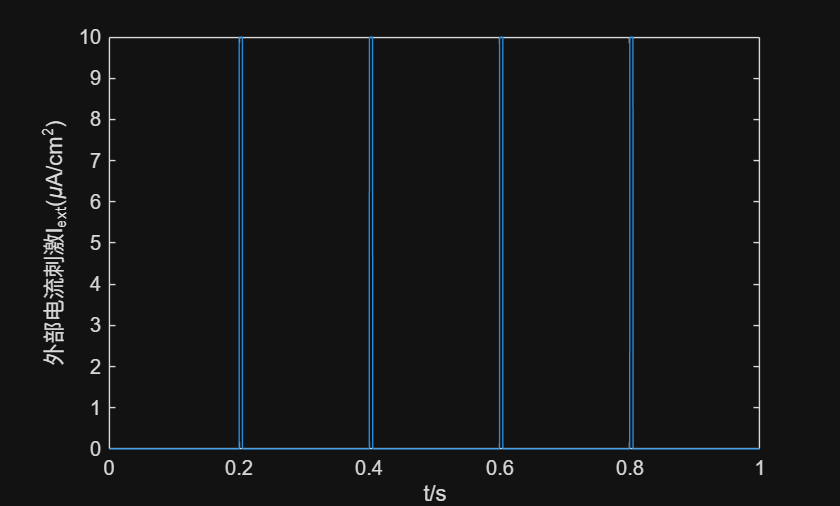

fs=10000;%采样频率
T=1;%总时长(s)
t=0:T/fs:T;%时间序列向量
Del=t(2)-t(1);%时间间隔
N=length(t);%时间离散化数量
T_ext=[0.2,0.4,0.6,0.8];%外部电流刺激，重复频率是5hz
%实际只用看中间的四次刺激
FunExt=rectpuls(t,1e-2);%外部电流刺激，间隔10ms
I_ext=@(u) pulstran(u,T_ext,FunExt,fs);%脉冲刺激向量
figure('Name','外部电流刺激I_{ext}-t示意图')
plot(t,10*I_ext(t))
hold on
xlabel('t/s');
ylabel('外部电流刺激I_{ext}(\muA/cm^{2})')

PPT中给出的微分方程是


$$$$
\begin{cases}
C_m \frac{dV}{dt} = -g_L(V-E_L) - \bar{g}_{Na} m^3 h (V-E_{Na}) - \bar{g}_K n^4 (V-E_K) + I_{app} \\
\frac{dm}{dt} = \alpha_m(V)(1-m) - \beta_m(V)m \\
\frac{dh}{dt} = \alpha_h(V)(1-h) - \beta_h(V)h \\
\frac{dn}{dt} = \alpha_n(V)(1-n) - \beta_n(V)n
\end{cases}
$$$$


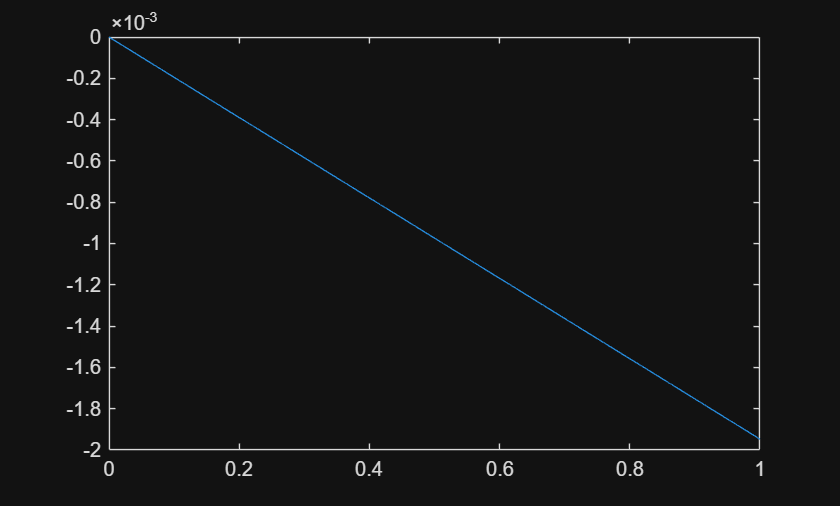

% 初始化，增加速度
V=zeros(1,N);m=zeros(1,N);
h=zeros(1,N);n=zeros(1,N);
fV=@(V,m,h,n,t) -g.L*(V-E.L)-g.Na*m^3*h*(V-E.Na)-g.K*n^4*(V-E.K)+I_ext(t);
fm=@(V,m) Alpha.m(V)*(1-m)-Beta.m(V)*m;
fh=@(V,h) Alpha.h(V)*(1-h)-Beta.h(V)*h;
fn=@(V,n) Alpha.n(V)*(1-n)-Beta.n(V)*n;
for i=1:N-1
    kV1=Del*fV(V(i),m(i),h(i),n(i),t(i));
    km1=Del*fm(V(i),m(i));
    kh1=Del*fh(V(i),h(i));
    kn1=Del*fn(V(i),n(i));

    kV2=Del*fV(V(i)+Del/2*kV1,m(i)+Del/2*km1,h(i)+Del/2*kh1,n(i)+Del/2*kn1,t(i)+Del/2);
    km2=Del*fm(V(i)+Del/2*kV1,m(i)+Del/2*km1);
    kh2=Del*fh(V(i)+Del/2*kV1,h(i)+Del/2*kh1);
    kn2=Del*fn(V(i)+Del/2*kV1,n(i)+Del/2*kn1);

    % kV3=Del*f(x(i)+Del/2,y(i)+1/2*kV2);
    kV3=Del*fV(V(i)+Del/2*kV2,m(i)+Del/2*km2,h(i)+Del/2*kh2,n(i)+Del/2*kn2,t(i)+Del/2);
    km3=Del*fm(V(i)+Del/2*kV2,m(i)+Del/2*km2);
    kh3=Del*fh(V(i)+Del/2*kV2,h(i)+Del/2*kh2);
    kn3=Del*fn(V(i)+Del/2*kV2,n(i)+Del/2*kn2);

    % kV4=Del*f(x(i)+Del,y(i)+kV3);
    kV4=Del*fV(V(i)+Del*kV3,m(i)+Del*km3,h(i)+Del*kh3,n(i)+Del*kn3,t(i)+Del);
    km4=Del*fm(V(i)+Del*kV3,m(i)+Del*km3);
    kh4=Del*fh(V(i)+Del*kV3,h(i)+Del*kh3);
    kn4=Del*fn(V(i)+Del*kV3,n(i)+Del*kn3);

    V(i+1)=V(i)+Del/6*(kV1+2*kV2+2*kV3+kV4);
    m(i+1)=m(i)+Del/6*(km1+2*km2+2*km3+km4);
    h(i+1)=h(i)+Del/6*(kh1+2*kh2+2*kh3+kh4);
    n(i+1)=n(i)+Del/6*(kn1+2*kn2+2*kn3+kn4);
end
figure
plot(t,V)

### 直流刺激-使用PPT中的参数和方程

### 脉冲刺激-使用文献中的参数和方程

### 直流刺激-使用文献中的参数和方程

## 任务 2：

  试计算直流刺激强度和神经元发放频率之间的关系   (提示: 神经元发放时间的确定)

## 任务 3：

  试计算一个动作电势过程中的通过单位面积细胞膜的钠离子总数目  

提示: 对一个动作电势过程中的钠电流进行积分, 得到通过钠离子通道的总电量, 除以元电荷电量  

$$

\begin{cases}

C_m \frac{dV}{dt} = -g_L(V-E_L) - \bar{g}_{Na} m^3 h (V - E_{Na}) - \bar{g}_K n^4 (V-E_K) + I_{app} \\

\frac{dm}{dt} = \alpha_m(V)(1-m) - \beta_m(V)m \\

\frac{dh}{dt} = \alpha_h(V)(1-h) - \beta_h(V)h \\

\frac{dn}{dt} = \alpha_n(V)(1-n) - \beta_n(V)n

\end{cases}

$$

 (图像图表标签) 

  Ion currents (μA/cm²)

  800

  (a)

  K

  700

  600

  500

  Na

  400

  300

  200

  100

  Cl

  0

  44

  46

  48

  Time (ms)

---

## 扩展：

membrane potential, the total electrical energy accumulated in the circuit at a given moment in time is

$H(t) = \frac{1}{2}CV^2 + H_{Na} + H_K + H_l, \quad (3)$

where the first term in the summation represents the electrical energy accumulated in the capacitor, and the other three terms are the respective energies in the batteries. The electrochemical energy accumulated in the batteries is unknown. In the model it is potentially unlimited as we do not contemplate the exhaustion of the batteries. In the real neuron, the intake of nutrients prevents the exhaustion of the ion pumps. Nevertheless, the rate of electrical energy provided to the circuit by a battery is known to be the electrical current through the battery times its electromotive force. Thus, the total derivative with respect to time of the above energy will be

$\dot{H}(t) = CV\dot{V} + i_{Na}E_{Na} + i_K E_K + i_l E_l. \quad (4)$

Let $I$ stand for the total external current that, one way or another, is injected through the membrane. According to the first equation in Eq. (1) we have

$C\dot{V} = I - i_{Na} - i_K - i_l,$

which substituted in Eq. (4) gives

$\dot{H} = VI - i_{Na}(V - E_{Na}) - i_K(V - E_K) - i_l(V - E_l).$

If we substitute Eq. (2) for the ion currents, we have for the energy rate in the circuit

$\dot{H} = VI - g_{Na}m^3h(V - E_{Na})^2 - g_K n^4 (V - E_K)^2$

$- g_l(V - E_l)^2, \quad (5)$

---

PHYSICAL REVIEW E 83, 031912 (2011)

  Energy and information in Hodgkin-Huxley neurons  

A. Moujahid, A. d'Anjou, and F. J. Torrealdea

 Department of Computer Science, University of the Basque Country, ES-20018 San Sebastian, Spain 

F. Torrealdea

 UCL Institute of Neurology, London WC1N 3BG, United Kingdom 

(Received 9 August 2010; revised manuscript received 21 January 2011; published 21 March 2011)

---

  Comment on "Energy and information in Hodgkin-Huxley neurons"  

Hideo Hasegawa 

 Department of Physics, Tokyo Gakugei University, Koganei, Tokyo 184-8501, Japan 

(Dated: June 30, 2011)

  Abstract  

In a recent paper [A. Moujahid, A. d'Anjou, F. J. Torrealdea and F. Torrealdea, Phys. Rev. E 83, 031912 (2011)], the authors have calculated the energy consumed in firing neurons by using the Hodgkin-Huxley (HH) model. The energy consumption rate adopted for the HH model yields a negative energy consumption meaning an energy transfer from an HH neuron to a source which is physically strange, although they have interpreted it as a biochemical energy cost. I propose an alternative expression for the power consumption which leads to a positive energy consumed in an HH neuron, presenting some model calculations which are compared to those in their paper.

PACS numbers: 87.19.1l, 87.19.lg, 87.19.ly, 87.18.Sn